# Stage 24

files = ['C:\Users\haosh\Documents\Lab\PFPE-Hao_Sheng\Data used in Fig.4\Stage 24\NS data and processed figures\0724_4pm_S4 _straight001.ns4'
    'C:\Users\haosh\Documents\Lab\PFPE-Hao_Sheng\Data used in Fig.4\Stage 24\NS data and processed figures\0724_4pm_S4 _straight002.ns4'
    'C:\Users\haosh\Documents\Lab\PFPE-Hao_Sheng\Data used in Fig.4\Stage 24\NS data and processed figures\0724_4pm_S4 _straight003.ns4'
    'C:\Users\haosh\Documents\Lab\PFPE-Hao_Sheng\Data used in Fig.4\Stage 24\NS data and processed figures\0724_4pm_S4 _straight004.ns4'
    ];
syncrhony_data_all = ones(4,1) * -1;
corr_data_stage24_all = ones(1,6) * -1;

for data_idx = 1:5 % Four files
    if data_idx ~= 5
        signals_raw = openNSx(files(data_idx, :), 'uv').Data;
        signals = downsample(smoothdata(signals_raw, 2)', 1000);
    else
        signals = xlsread("C:\Users\haosh\Documents\Lab\PFPE-Hao_Sheng\Data used in Fig.4\Stage 24\NS data and processed figures\07252021_4pm_s4001-100resample.xlsx");
        signals = downsample(signals, 10);
    end
    
    fs = 10; % Hz
    window_size = 2; % points; sec
    minpeakdistance = 1; % points; sec
    minpeakwidth = 1; % points; sec
    minpeakheight = 150;
    
    [pks_1, locs_1] = findpeaks(signals(:,1)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight', minpeakheight);
    [pks_2, locs_2] = findpeaks(signals(:,2)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight', minpeakheight);
    [pks_3, locs_3] = findpeaks(signals(:,3)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight', minpeakheight);
    [pks_4, locs_4] = findpeaks(signals(:,4)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight', minpeakheight);
    
    step = 2000;
    
    total_time_point = size(signals, 1);
    syncrhony_data = determine_synchrony(locs_1, locs_2, locs_3, locs_4, window_size*fs, total_time_point);
    syncrhony_data_all = [syncrhony_data_all syncrhony_data];

    pre_time = 2000; % ms
    post_time = 2000; % ms
    pre = pre_time/1000*fs;
    post = post_time/1000*fs;
    
    data_stage24 = stage24_data_prepare(signals', syncrhony_data'/fs, fs, pre, post);
    corr_data_stage24 = correlation_cal(data_stage24);
    corr_data_stage24_all = [corr_data_stage24_all; corr_data_stage24];
end

corr_data_stage24_all = corr_data_stage24_all(2:end, :);

syncrhony_data_all = syncrhony_data_all(:, 2:end);
distribution_data_24 = time_delay_dist(syncrhony_data_all);

distribution_data_24_std = std((distribution_data_24')/fs);

# Stage 26

signals_raw = openNSx('C:\Users\haosh\Documents\Lab\PFPE-Hao_Sheng\Data used in Fig.4\Stage 26\NS data and processed figures\07252021_4pm_s4002.ns4', 'uv').Data;
signals = smoothdata(downsample(signals_raw',100), 1);
fs = 100; % Hz
window_size = 2; % points; sec
minpeakdistance = 1; % points; sec
minpeakwidth = 0.3; % points; sec
minpeakheight = 20;

[pks_1, locs_1] = findpeaks(signals(:,1)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight',minpeakheight);
[pks_2, locs_2] = findpeaks(signals(:,2)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight',minpeakheight);
[pks_3, locs_3] = findpeaks(signals(:,3)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight',minpeakheight);
[pks_4, locs_4] = findpeaks(signals(:,4)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight',minpeakheight);

total_time_point = size(signals, 1);
syncrhony_data = determine_synchrony(locs_1, locs_2, locs_3, locs_4, window_size*fs, total_time_point);
pre_time = 300; % ms
post_time = 700; % ms

pre = pre_time/1000*fs;
post = post_time/1000*fs;
data_stage26 = stage24_data_prepare(signals', syncrhony_data'/fs, fs, pre, post);
corr_data_stage26 = correlation_cal(data_stage26);
distribution_data_26 = time_delay_dist(syncrhony_data);
distribution_data_26_std = std((distribution_data_26')/fs);

# Stage 40 LFP


signals_raw = openNSx('C:\Users\haosh\Documents\Lab\PFPE-Hao_Sheng\Data used in Fig.4\Stage 40\NS data and processed figures\07282021_4PM_S4003.ns4', 'uv').Data;
signals_raw = lowpass(signals_raw', 100, 10000);
signals = smoothdata(signals_raw, 1);
window_size = 2; % points; sec
minpeakdistance = 1; % points; sec
minpeakwidth = 0.3; % points; sec
minpeakheight = 3;

fs = 10000;
[pks_1, locs_1] = findpeaks(signals(:,1)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight', minpeakheight);
[pks_2, locs_2] = findpeaks(signals(:,2)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight', minpeakheight);
[pks_3, locs_3] = findpeaks(signals(:,3)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight', minpeakheight);
[pks_4, locs_4] = findpeaks(signals(:,4)', 'MinPeakDistance', minpeakdistance*fs, 'MinPeakWidth', minpeakwidth*fs, 'MinPeakHeight', minpeakheight);

total_time_point = size(signals, 1);
syncrhony_data = determine_synchrony(locs_1, locs_2, locs_3, locs_4, window_size*fs, total_time_point);
pre_time = 1500; % ms
post_time = 1500; % ms


pre = pre_time/1000*fs;
post = post_time/1000*fs;
data_stage40_lfp = stage24_data_prepare(signals', syncrhony_data'/fs, fs, pre, post);
corr_data_stage40_lfp = correlation_cal(data_stage40_lfp);
distribution_data_40_lfp = time_delay_dist(syncrhony_data);

distribution_data_40_lfp_std = std((distribution_data_40_lfp')/fs);

# Synchrony Boxchart

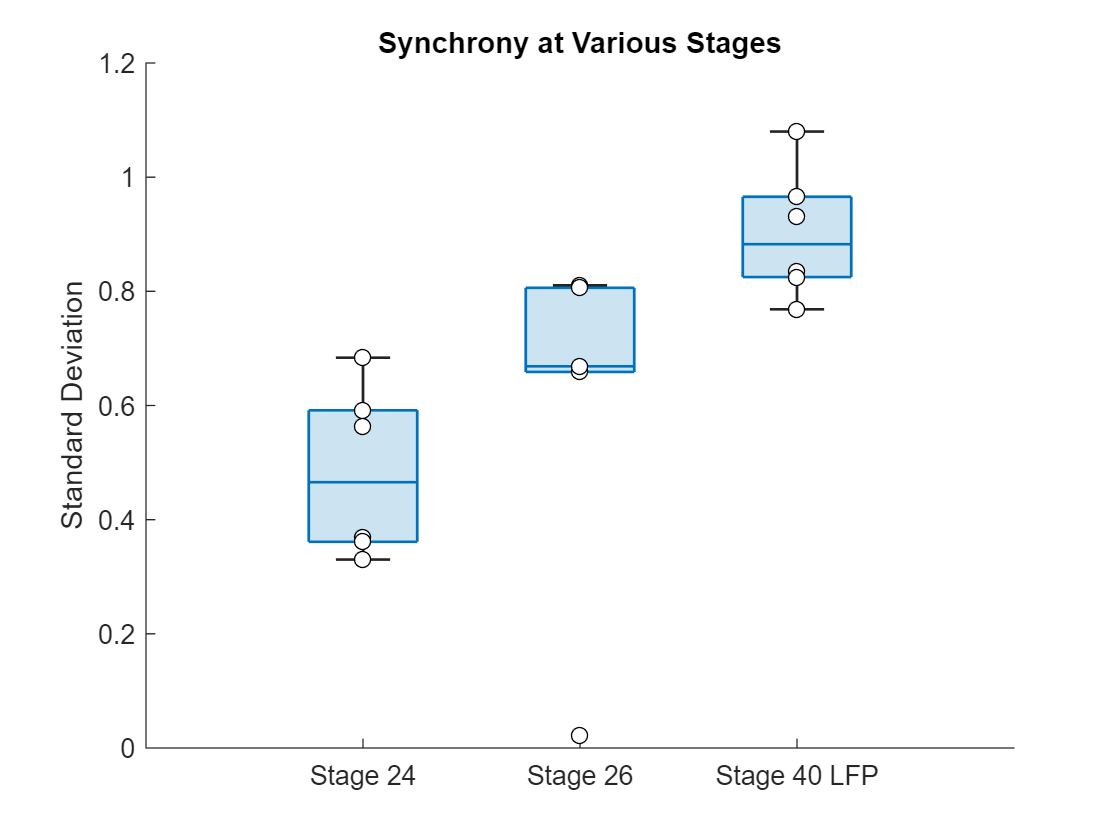

distribution_data_stds = [distribution_data_24_std distribution_data_26_std distribution_data_40_lfp_std];
synnchrony_all =  [distribution_data_24_std' distribution_data_26_std' distribution_data_40_lfp_std'];
stages = ["Stage 24", "Stage 26", "Stage 40 LFP"];
spike_num = 6;
g = [ones(spike_num, 1); ones(spike_num, 1)*2; ones(spike_num, 1)*3];
namedstages = categorical(g,1:3,stages);
b = boxchart(namedstages, distribution_data_stds, 'MarkerStyle', 'none');
ylabel('Standard Deviation')
title('Synchrony at Various Stages')
hold on
scatter(ones(1,6), distribution_data_24_std, 'MarkerEdgeColor', 'black', 'MarkerFaceColor','white')
scatter(ones(1,6)*2, distribution_data_26_std, 'MarkerEdgeColor', 'black', 'MarkerFaceColor','white')
scatter(ones(1,6)*3, distribution_data_40_lfp_std, 'MarkerEdgeColor', 'black', 'MarkerFaceColor','white')

# Stage 40

load raster_plot.mat
load '07282021_4pm_s4003_raw_4channel.mat'

waveform = data;
raster = cluster_class;
pre_time = 700; % ms
post_time = 700; % ms

fs = 10000;
pre = pre_time/1000*fs;
post = post_time/1000*fs;

time_stamp = raster(:,2)' / 1000; %ms -> s
signals = data';

data_stage40 = stage40_data_prepare(signals, time_stamp, fs, pre, post);
corr_data_stage40 = correlation_cal(data_stage40);

# Correlation Violin Plot

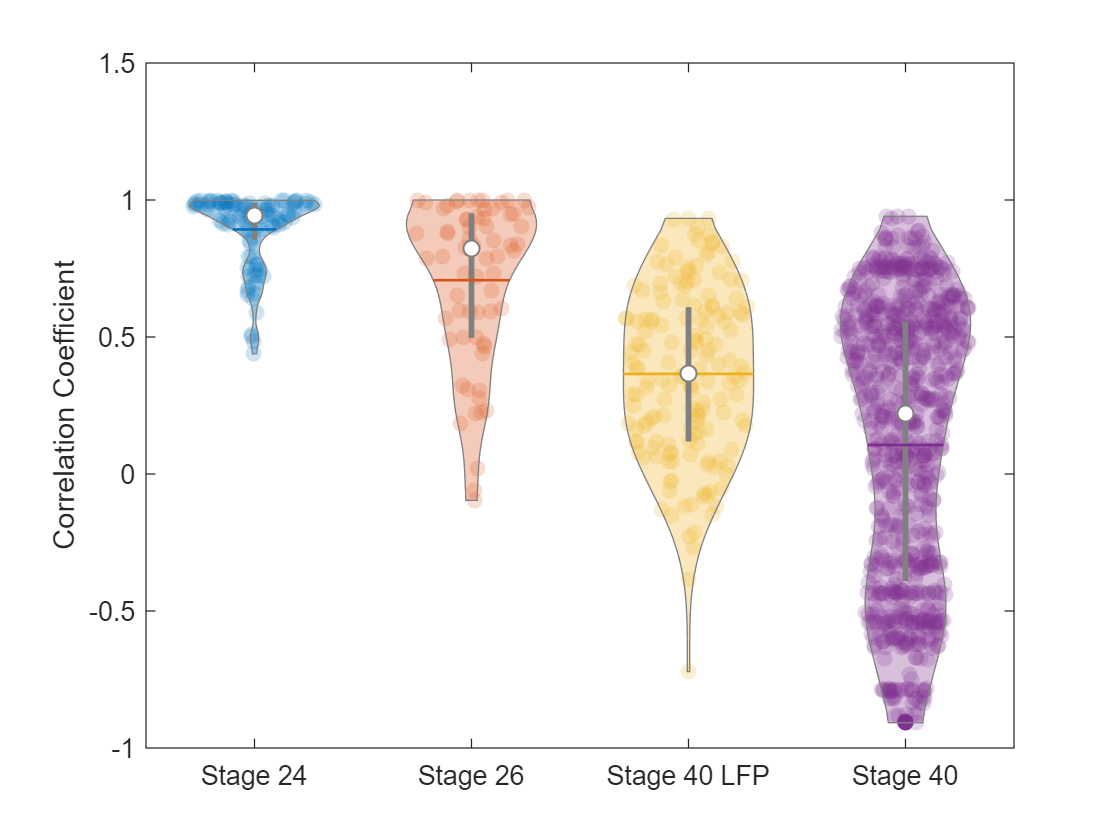

x1 = reshape(corr_data_stage24_all, [],1);
x2 = reshape(corr_data_stage26, [],1);
x3 = reshape(corr_data_stage40_lfp, [],1);
x4 =reshape(corr_data_stage40, [],1);
x = [x1 ; x2; x3; x4];
g =  [zeros(length(x1), 1); ones(length(x2), 1);  ones(length(x3), 1)*2; ones(length(x4), 1)*3];

figure
v = violinplot(x, g, 'ShowData', true, 'ShowMean', true,'ShowWhiskers', false);%{,'QuartileStyle','none'
v(1).ScatterPlot.MarkerFaceAlpha = 0.2;
v(2).ScatterPlot.MarkerFaceAlpha = 0.2;
v(3).ScatterPlot.MarkerFaceAlpha = 0.2;
v(4).ScatterPlot.MarkerFaceAlpha = 0.2;
hold off
xticks([1 2 3 4])
xticklabels({'Stage 24', 'Stage 26', 'Stage 40 LFP', 'Stage 40'})
ylabel('Correlation Coefficient')
ylim([-1 1.5])

function [synchrony_data] = determine_synchrony(locs_1, locs_2, locs_3, locs_4, window_size, total_time_point)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
    begin = 0;
    back = begin + window_size;
       
    synchrony_data = ones(4, 1) * -1;

    while back <= total_time_point
        flag_1 = sum(((locs_1 >= begin) + (locs_1 <= back)) == 2);
        loc_1 = locs_1(((locs_1 >= begin) + (locs_1 <= back)) == 2);

        flag_2 = sum(((locs_2 >= begin) + (locs_2 <= back)) == 2);
        loc_2 = locs_2(((locs_2 >= begin) + (locs_2 <= back)) == 2);

        flag_3 = sum(((locs_3 >= begin) + (locs_3 <= back)) == 2);
        loc_3 = locs_3(((locs_3 >= begin) + (locs_3 <= back)) == 2);
        
        flag_4 = sum(((locs_4 >= begin) + (locs_4 <= back)) == 2);
        loc_4 = locs_4(((locs_4 >= begin) + (locs_4 <= back)) == 2);

        begin = begin + 1;
        back = back + 1;
        combined_flag = [flag_1  flag_2 flag_3 flag_4];
        if sum(combined_flag == 0) ~= 0
            continue
        elseif sum(combined_flag) == 4
            synchrony_data = [synchrony_data [loc_1; loc_2; loc_3; loc_4]];
            locs_1(locs_1 == loc_1) = [];
            locs_2(locs_2 == loc_2) = [];
            locs_3(locs_3 == loc_3) = [];
            locs_4(locs_4 == loc_4) = [];
        end
    end
    synchrony_data = synchrony_data(:, 2:end);   
end

function [data] = stage24_data_prepare(signals, time_stamp, fs, pre, post)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
   
    data = zeros(4, pre + post + 1, size(time_stamp, 1));

    for spike_idx = 1:size(time_stamp, 1)
        spike_time = time_stamp(spike_idx, :); %s
        for channel_idx = 1:size(spike_time, 2)
            spike_time_index = ceil(spike_time(channel_idx) * fs);
            if (spike_time_index - pre) < 1 | (spike_time_index + post) > size(signals, 2)
                break
            end
            data(channel_idx, :, spike_idx) =  signals(channel_idx, spike_time_index - pre:spike_time_index + post);
        end
    end
end


function [data] = stage40_data_prepare(signals, time_stamp, fs, pre, post)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
   
    data = zeros(4, pre + post + 1, length(time_stamp));

    for spike_idx = 1:length(time_stamp)
        spike_time = time_stamp(spike_idx); %s
        spike_time_index = round(spike_time * fs);
        if (spike_time_index - pre) < 1 | (spike_time_index + post) > size(signals, 2)
            break
        end
        data(:, :, spike_idx) = signals(:, spike_time_index - pre:spike_time_index + post);
    end
end

function [corr_data] = correlation_cal(data)
    corr_data = zeros(size(data, 3), 6);
    for spike_idx = 1:size(data, 3)
        waveform_all_channel = data(:, :, spike_idx)';
        corr_matrix = corrcoef(waveform_all_channel);
        corr_spike_val = [];
        for diag_idx = 1:3
            corr_spike_val = [corr_spike_val diag(corr_matrix, diag_idx)'];
        end
        corr_data(spike_idx, :) = corr_spike_val;
    end
end

function [distribution_data] = time_delay_dist(synchrony_data)
%UNTITLED Summary of this function goes here
%   Detailed explanation goes here
    distribution_data = zeros(6, size(synchrony_data, 2));
    idx = 1;
    for channel1 =  1:size(synchrony_data, 1)
        for channel2 = 1:size(synchrony_data, 1)
            if channel1 >= channel2
                continue
            end
            distribution_data(idx, :) = synchrony_data(channel1, :) - synchrony_data(channel2, :);
            idx = idx + 1;
        end
    end
end